# Laboratorium 4

# Analiza harmoniczna - część 2

Janusz Pawlicki

## 1 Wstęp - Analiza harmoniczna sygnałów

### 1.1 Rozwijanie sygnałów w szereg Fouriera

Jednym z podstawowych narzędzi matematycznych pozwalających na badanie rzeczywistych sygnałów ciągłych jest fourierowska analiza harmoniczna polegająca na rozwinięciu nieskończonego okresowego sygnału ciągłego w tzw. szereg Fourier'a. Umożliwia ona m.in. analizę zachowania liniowych i stacjonarnych układów dynamicznych (mechanicznych, elektrycznych i innych) w stanie ustalonym podczas pobudzenia sygnałem ciągłym okresowym. Pozwala modelować proces konwersji sygnału analogowego (ciągłego) na postać cyfrową tj. przetwarzanie A/C (Analog/Cyfra). Jest również wykorzystywana w opisywaniu procesu modulacji oraz ocenie zniekształceń sygnałów.

Na potrzeby ćwiczenia przyjmujemy, że funkcja x(t) opisująca sygnał ciągły ma charakter rzeczywisty (a nie zespolony) i spełnia warunek x(t) = x∗(t) oraz warunki Dirichleta:

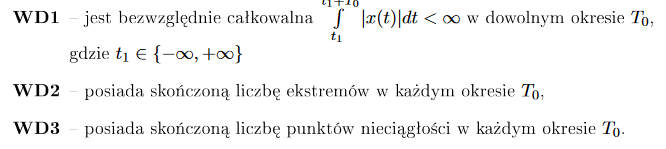

Rozwini¦cie sygnału w szereg Fouriera i transformacja odwrotna opisana może być za pomocą jednej z trzech postaci: wykładniczej (1, 2), fazowej (3, 4) i trygonometrycznej (5, 6):

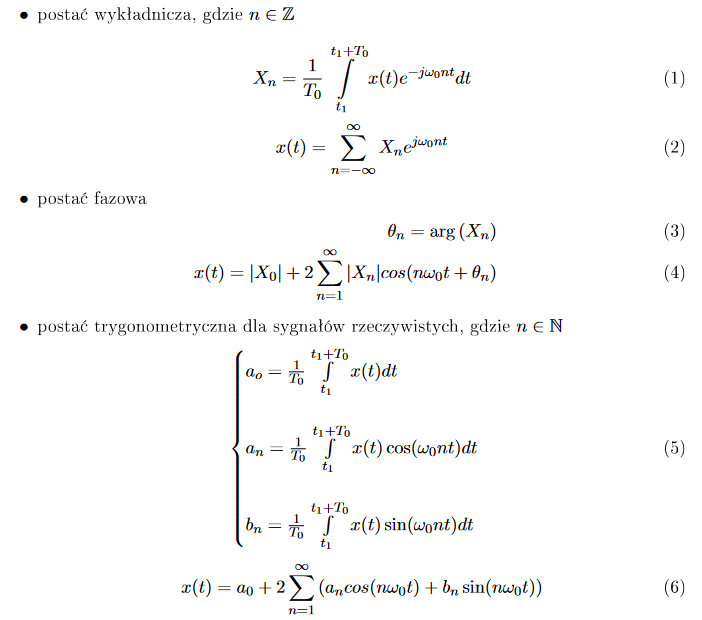

### 1.2 Współczynnik zawartości harmonicznych

Jednym z parametrów charakteryzujących sygnały ciągłe jest współczynnik zawartości harmonicznych (11) THD (ang. Total Harmonic Distortion) opisujący stopień odkształcenia sygnału od idelanego przebiegu sinusoidalnego. Przesunięcie fazowe nie ma znaczenia ponieważ do jego wyliczenia wykorzystuje się skuteczne wartości RMS (ang. Root Mean Square) poszczególnych składowych funkcji harmonicznych.

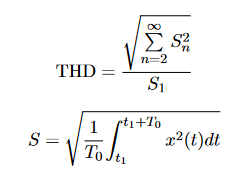

## 2 Przebieg laboratorium - zadania

### Zadania z poprzedniej części

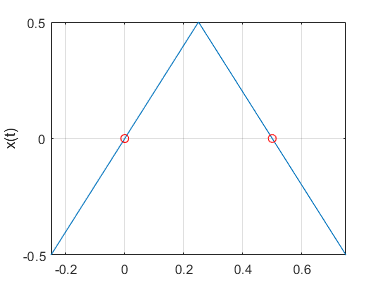

syms t t1 t2 offset x

T0 = 1.0;
t1 = -0.5;
t2 = t1 + T0;

offset = T0/4;

f0 = 1/T0;

w0 = 2*pi*f0;

BND = [t1,t2] + offset;

x = triangularPulse(t1, 0.0, t2, t-offset) - 0.5;

figure
fplot(x, BND), grid on, ylabel('x(t)')

hold on

plot(0, 0, 'ro')
plot(0.5, 0, 'ro')

hold off

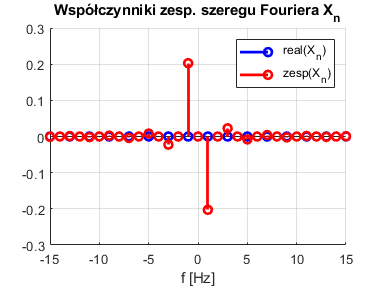


%------------------------------------------------------------------

NT = 15;

X=[];

ind = -NT:NT;

for n = ind
    Xn = (1/T0)*int(x*exp(-1i*w0*n*t),t,BND);
    X(n + NT + 1) = Xn;
end

figure

hold on

stem(ind*f0, real(X),'b','LineWidth',2);

xlabel('f [Hz]')

stem(ind*f0, imag(X),'r','LineWidth',2);

grid on

legend('real(X_n)','zesp(X_n)','Location','NorthEast'),

title('Współczynniki zesp. szeregu Fouriera X_n')

hold off

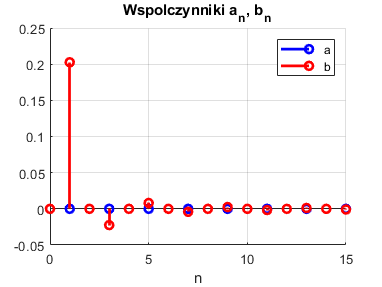


%-------------------------------------------------------------------------------

NT = 0:15;

a=[];
b=[];

for n = NT
    a(n+1) = (1/T0)*int(x*cos(w0*n*t),t,BND);
    b(n+1) = (1/T0)*int(x*sin(w0*n*t),t,BND);
end

figure; 

grid on

hold on

stem(NT,a,'b','LineWidth',2);

xlabel('n')

stem(NT,b,'r','LineWidth',2);

legend('a','b'),

title('Wspolczynniki a_n, b_n')

hold off

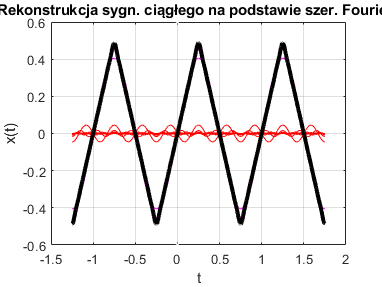


%-------------------------------------------------------------------------------

step = (BND(2)-BND(1))/1000;

tt = [BND(1)-T0 : step : BND(2) + T0];

xx = zeros(1,length(tt));
xx = xx + a(1);

figure;

plot(tt,xx,'m')

grid on 

hold on

plot([0, 0],[-0.6, 0.6], 'w.'),

xlabel('t'); ylabel('x(t)');

pause(0.5)

for n = NT
    xx_n = 2*(a(n+1)*cos(w0*n*tt) + b(n+1)*sin(w0*n*tt));
    xx = xx + xx_n;
    plot(tt,xx_n,'r');
    plot(tt,xx,'m');
    title(sprintf('n = %d',n+1));
    pause(0.5)
end

plot(tt,xx,'k','LineWidth',3);
title('Rekonstrukcja sygn. ciągłego na podstawie szer. Fouriera')

hold off

## 2.1 Zadanie 5

Wykorzystując wcześniejsze programy, wykonaj rekonstrukcję 3-ch okresów przebiegu wejściowego na podstawie elementów szeregu zespolonego. Porównaj rezultaty rekonstrukcji z tymi uzyskanymi w ćw. 4 oraz z ciągłym przebiegiem widocznym na rysunku 1. Wylicz błąd aproksymacji przebiegu. W sprawozdaniu zanotuj wartość błędu oraz umieść kod programu. Opisz jaki wpływ na rekonstrukcję sygnału ma ogranicznie liczby elementów szeregu.

NT = 15;

tt = linspace(BND(1)-T0, BND(2) + T0, 3000)

tt =    -1.2500   -1.2490   -1.2480   -1.2470   -1.2460   -1.2450   -1.2440   -1.2430   -1.2420   -1.2410   -1.2400   -1.2390   -1.2380   -1.2370   -1.2360   -1.2350   -1.2340   -1.2330   -1.2320   -1.2310   -1.2300   -1.2290   -1.2280   -1.2270   -1.2260   -1.2250   -1.2240   -1.2230   -1.2220   -1.2210   -1.2200   -1.2190   -1.2180   -1.2170   -1.2160   -1.2150   -1.2140   -1.2130   -1.2120   -1.2110   -1.2100   -1.2090   -1.2080   -1.2070   -1.2060   -1.2050   -1.2040   -1.2030   -1.2020   -1.2010


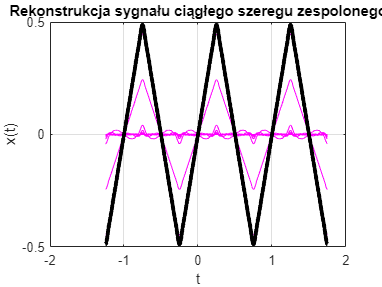

xx = zeros(1,length(tt));

figure;

plot(tt,xx,'m'); 
grid on; 
hold on;

xlabel('t'); ylabel('x(t)');

for n = -NT : NT
    xx_n = X(-n+NT+1) * exp((-1)*1j*2*pi*f0*n*tt);
    xx = xx + xx_n;
    plot(tt,real(xx),'m');
end
plot(tt,real(xx),'k','LineWidth',3);
grid on;
hold on
title('Rekonstrukcja sygnału ciągłego szeregu zespolonego')



% obliczanie błędu aproksymacji
syms err
pars_wave = int(x.^2,t,BND)/T0

$$pars\_wave = \frac{1}{12}$$

pars_series = sum(abs(X).^2)

pars_series = 0.0833

err_abs = double(abs(pars_wave - pars_series))

err_abs = 3.3160e-06

err_rel = double(err_abs / pars_wave) * 100

err_rel = 0.0040

Błąd aproksymacji został wyliczony na podstawie twierdzenia Parsevala. Energia sygnału ciągłego powinna być równa energii szeregu Fouriera tego sygnału. Obie energie zostały wyliczone, a następnie porównane. Wskaźnikiem błędu jest więc różnica między nimi. Różnica jest bezwzględnie niewielka, wartość błędu obliczonego w ten sposób wynosi 3,316 ∗ 10^(−6)

W teorii, mniejsza liczba wyrazów szeregu oznacza gorszą jakość rekonstruowanego sygnału. Trzykrotne zmniejszenie liczby wyrazów szeregu poskutkowało znaczącym wzrostem błędu, który wyniósł 6 ∗ 10^(−5), a więc wzrósł 18-krotnie – tak więc użyty sposób może być wiarygodnym wskaźnikiem błędu aproksymacji.

## 2.2 Zadanie 6

### A)

Wylicz metodą symboliczną współczynnik wartości skutecznej dla przebiegu sinusoidalnego. Wynik zamień na postać numeryczną i przypisz do zmiennej `skd`. Zweryfikuj rezultat z obliczeniami analitycznymi ("na papierze") lub z tablicami. Podaj wzór na współczynnik sk i sprawdź poprawność wyliczenia `skd`.

W teorii, wartość skuteczna sygnału sinusoidalnego wynosi 𝐴/√2, gdzie A to amplituda sygnału.

Dla sygnału o amplitudzie 1, wartość skuteczna to 0.707. Potwierdzają to obliczenia symboliczne:

syms skut
skut = sqrt(int(sin(t)^2,t,[0 2*pi])/(2*pi));
skd = double(skut)

skd = 0.7071

### B) 

Wylicz wartość skuteczną sygnału ciągłego x(t) zdefiniowanego w Ćw. 1.

skut1 = sqrt(int(x^2,t,BND)/T0);
skut1_db = double(skut1)

skut1_db = 0.2887

### C)

Wylicz wartość skuteczną sygnału ciągłego zrekonstruowanego na podstawie 16-tu funkcji bazowych z Ćw. 4.

skut_rek = sqrt(trapz(real(xx(1001:2001)).^2)/1000)

skut_rek = 0.2888

Dla 𝑛 = 5 współczynników wynosi on 0.1198 i nieznacznie rośnie wraz ze wzrostem liczby współczynników, wynosząc 0.121 dla 15 współczynników. Wartość ta jest równa teoretycznej wartości, obliczonej analitycznie.

## 2.2 Zadanie 7

Stosując obliczenia symboliczne wyznacz numeryczną wartość współczynnika zniekształceń harmonicznych THD sygnału dla liczby współczynników n ∈ {5, 10, 15}. Kod programu oraz wyniki wraz z wnioskami umieść w sprawozdaniu. Znajdź w literaturze analityczną formułę na wartość skuteczną oraz współczynnik THD przebiegu i oceń dokładność.

s = 0;
for n = 2:NT
    s = s + abs(a(n+1)+1j*b(n+1)).^2/2;
    thd = sqrt(s)/(abs(a(2)+1j*b(2))/sqrt(2))
end

thd = 0

thd = 0.1111

thd = 0.1111

thd = 0.1181

thd = 0.1181

thd = 0.1198

thd = 0.1198

thd = 0.1205

thd = 0.1205

thd = 0.1208

thd = 0.1208

thd = 0.1209

thd = 0.1209

thd = 0.1210

## 3 Zadanie domowe

## 3.1 Prostokątny

### 3.1.1

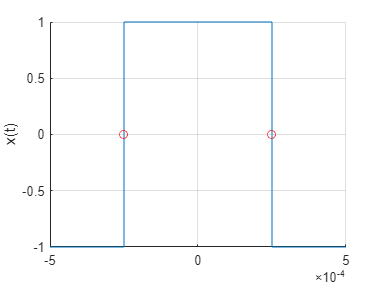

T0 = 1/1000;
t1 = -T0/2;
t2 = t1 + T0;
offset = 0;
f0 = 1/T0;
w0 = 2*pi*f0;
BND = [t1,t2] + offset;
x = 2*(rectangularPulse(t1/2, t2/2, t)-0.5);
figure
hold on
fplot(x, BND)
xlim(BND)
grid on;
ylabel('x(t)')
plot(t1/2, 0, 'ro')
plot(t2/2, 0, 'ro')
hold off

### 3.1.2

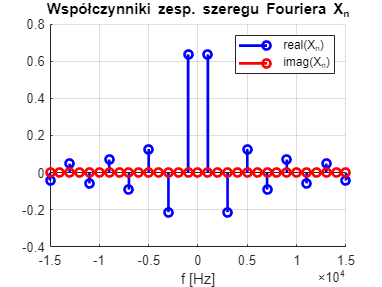

NT = 15;
X=[];
ind=-NT:NT;
for n = ind
    Xn = (1/T0)*int(x*exp(-1i*w0*n*t),t,BND);
    X(n+NT+1)=Xn;
end
figure; hold on
stem(ind*f0,real(X),'b','LineWidth',2);
xlabel('f [Hz]')
stem(ind*f0,imag(X),'r','LineWidth',2);
grid on
legend('real(X_n)','imag(X_n)','Location','NorthEast'),
title('Współczynniki zesp. szeregu Fouriera X_n')
hold off

### 3.1.3

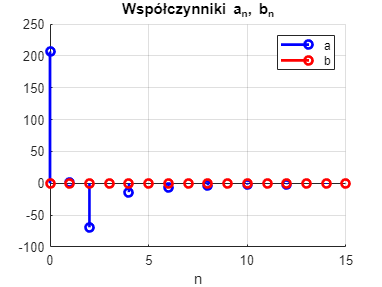

a=[];
b=[];
for n = 0:NT
    a(n+1) = (1/T0)*int(x*cos(w0*n*t),t,BND);
    b(n+1) = (1/T0)*int(x*sin(w0*n*t),t,BND);
end

figure(3); hold on, grid on
stem(0:NT,a,'b','LineWidth',2);
xlabel('n')
stem(0:NT,b,'r','LineWidth',2);
legend('a','b'),
title('Współczynniki a_n, b_n')
hold off

### 3.1.4

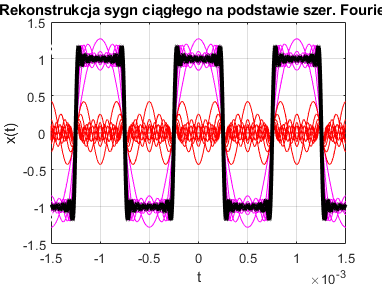

step = (BND(2)-BND(1))/1000;
tt = [BND(1)-T0 : step : BND(2)+T0];
xx = zeros(1,length(tt));
xx = xx + a(1);

figure;
plot(tt,xx,'m');  grid on, hold on;
plot([tt(1),tt(2)],[max(xx)-0.1,min(xx)+0.1], 'r'),
pause(0.5)
xlabel('t'); ylabel('x(t)');

for n=1:NT
    xx_n=2*(a(n+1)*cos(w0*n*tt)+b(n+1)*sin(w0*n*tt));
    xx = xx + xx_n;
    plot(tt,xx_n,'r');
    plot(tt,xx,'m');
    plot([tt(1),tt(2)],[max(xx)-0.1,min(xx)+0.1],'w.')
    title(sprintf('n = %d',n+1));
    pause(0.5)
end
 
plot(tt,xx,'k','LineWidth',3); grid on, hold on
plot([tt(1),tt(2)],[max(xx)-0.1,min(xx)+0.1],'w.')
title('Rekonstrukcja sygn ciągłego na podstawie szer. Fouriera')
hold off

### 3.1.5

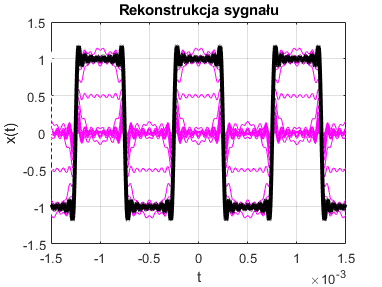

xx = zeros(1,length(tt));

figure(5);
plot(tt,xx,'m');  grid on, hold on;
pause(0.5)
xlabel('t'); ylabel('x(t)');

for n=-NT:NT
    xx_n=X(n+NT+1)*exp(1i*w0*n*tt);
    xx = xx + xx_n;
    pause(0.5);
    plot(tt,real(xx),'m');
    plot([tt(1),tt(2)],[max(real(xx))-0.1, min(real(xx))+0.1],'w.')
end

plot(tt,real(xx),'k','LineWidth',3); grid on, hold on
plot([tt(1),tt(2)],[max(real(xx))-0.1,min(real(xx))+0.1],'w.')
title('Rekonstrukcja sygnału')
hold off


% błąd aproksymacji

syms err
pars_wave = int(x.^2,t,BND)/T0

$$pars\_wave = 1$$

pars_series = sum(abs(X).^2)

pars_series = 0.9747

err_abs = double(abs(pars_wave - pars_series))

err_abs = 0.0253

err_rel = double(err_abs / pars_wave) * 100

err_rel = 2.5297

### 3.1.6 A)

syms skut
skut = sqrt(int(sin(t)^2,t,[0 2*pi])/(2*pi));
skd = double(skut)

skd = 0.7071

### 3.1.6 B)

skut1 = sqrt(int(x^2,t,BND)/T0)

$$skut1 = 1$$

### 3.1.6 C)

skut_xx = sqrt(trapz(real(xx(1001:2001)).^2)/1000)

skut_xx = 0.9873

### 3.1.7

s = 0;
for n = 2:NT
    s = s + abs(a(n+1)+1j*b(n+1)).^2/2;
    thd = sqrt(s)/(abs(a(2)+1j*b(2))/sqrt(2))
end

thd = 0

thd = 0.3333

thd = 0.3333

thd = 0.3887

thd = 0.3887

thd = 0.4141

thd = 0.4141

thd = 0.4288

thd = 0.4288

thd = 0.4383

thd = 0.4383

thd = 0.4450

thd = 0.4450

thd = 0.4500

## 3.2 Wyprostowany dwupołówkowo sinus

### 3.2.1 

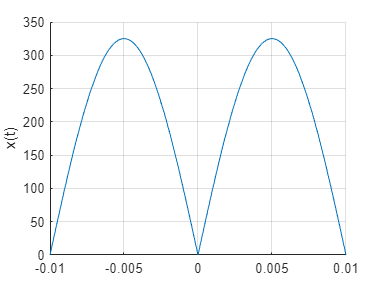

syms t t1 t2 offset x
T0 = 1/50;
t1 = -T0/2;
t2 = t1 + T0;
offset = 0;
f0 = 1/T0;
w0 = 2*pi*f0;
BND = [t1,t2] + offset;
x = abs(325*sin(50*2*pi*t));
figure
hold on
fplot(x, BND)
xlim(BND)
grid on;
ylabel('x(t)')
hold off

%Funkcja jest zawsze dodatnia stąd brak punktów wymaganych w zad 1

### 3.2.2

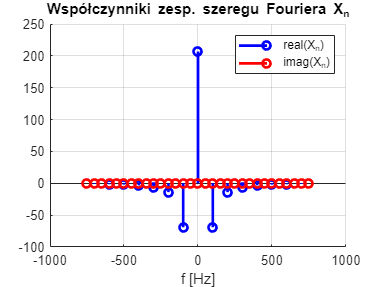

NT = 15;
X=[];
ind=-NT:NT;
for n = ind
    Xn = (1/T0)*int(x*exp(-1i*w0*n*t),t,BND);
    X(n+NT+1)=Xn;
end
figure; hold on
stem(ind*f0,real(X),'b','LineWidth',2);
xlabel('f [Hz]')
stem(ind*f0,imag(X),'r','LineWidth',2);
grid on
legend('real(X_n)','imag(X_n)','Location','NorthEast'),
title('Współczynniki zesp. szeregu Fouriera X_n')
hold off

### 3.2.3

a=[];
b=[];
for n = 0:NT
    a(n+1) = (1/T0)*int(x*cos(w0*n*t),t,BND);
    b(n+1) = (1/T0)*int(x*sin(w0*n*t),t,BND);
end

figure(3); hold on, grid on
stem(0:NT,a,'b','LineWidth',2);
xlabel('n')
stem(0:NT,b,'r','LineWidth',2);
legend('a','b'),
title('Współczynniki a_n, b_n')
hold off

### 3.2.4

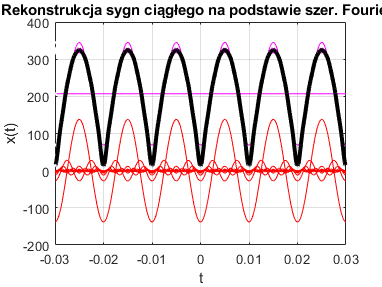

step = (BND(2)-BND(1))/1000;
tt = [BND(1)-T0 : step : BND(2)+T0];
xx = zeros(1,length(tt));
xx = xx + a(1);

figure;
plot(tt,xx,'m');  grid on, hold on;
plot([tt(1),tt(2)],[max(xx)-0.1,min(xx)+0.1], 'r'),
pause(0.5)
xlabel('t'); ylabel('x(t)');

for n=1:NT
    xx_n=2*(a(n+1)*cos(w0*n*tt)+b(n+1)*sin(w0*n*tt));
    xx = xx + xx_n;
    plot(tt,xx_n,'r');
    plot(tt,xx,'m');
    plot([tt(1),tt(2)],[max(xx)-0.1,min(xx)+0.1],'w.')
    title(sprintf('n = %d',n+1));
    pause(0.5)
end
 
plot(tt,xx,'k','LineWidth',3); grid on, hold on
plot([tt(1),tt(2)],[max(xx)-0.1,min(xx)+0.1],'w.')
title('Rekonstrukcja sygn ciągłego na podstawie szer. Fouriera')
hold off

### 3.2.5

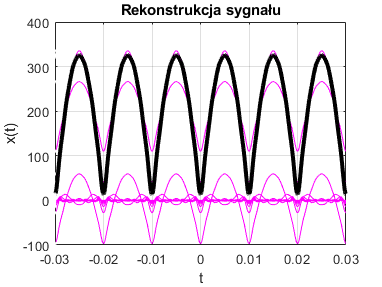

xx = zeros(1,length(tt));

figure(5);
plot(tt,xx,'m');  grid on, hold on;
pause(0.5)
xlabel('t'); ylabel('x(t)');

for n=-NT:NT
    xx_n=X(n+NT+1)*exp(1i*w0*n*tt);
    xx = xx + xx_n;
    pause(0.5);
    plot(tt,real(xx),'m');
    plot([tt(1),tt(2)],[max(real(xx))-0.1, min(real(xx))+0.1],'w.')
end

plot(tt,real(xx),'k','LineWidth',3); grid on, hold on
plot([tt(1),tt(2)],[max(real(xx))-0.1,min(real(xx))+0.1],'w.')
title('Rekonstrukcja sygnału')
hold off


% błąd aproksymacji

syms err
pars_wave = int(x.^2,t,BND)/T0

$$pars\_wave = \frac{105625}{2}$$

pars_series = sum(abs(X).^2)

pars_series = 5.2808e+04

err_abs = double(abs(pars_wave - pars_series))

err_abs = 4.2131

err_rel = double(err_abs / pars_wave) * 100

err_rel = 0.0080

### 3.2.6 A)

syms skut
skut = sqrt(int(sin(t)^2,t,[0 2*pi])/(2*pi));
skd = double(skut)

skd = 0.7071

### 3.2.6 B)

skut1 = sqrt(int(x^2,t,BND)/T0)

$$skut1 = \frac{325\,\sqrt{2}}{2}$$

### 3.2.6 C)

skut_xx = sqrt(trapz(real(xx(1001:2001)).^2)/1000)

skut_xx = 229.8005

### 3.2.7

s = 0;
for n = 2:NT
    s = s + abs(a(n+1)+1j*b(n+1)).^2/2;
    thd = sqrt(s)/(abs(a(2)+1j*b(2))/sqrt(2))
end

thd = Inf

thd = Inf

thd = Inf

thd = Inf

thd = Inf

thd = Inf

thd = Inf

thd = Inf

thd = Inf

thd = Inf

thd = Inf

thd = Inf

thd = Inf

thd = Inf

## 3.3 Modyfikowana sinusoida

### 3.3.1 

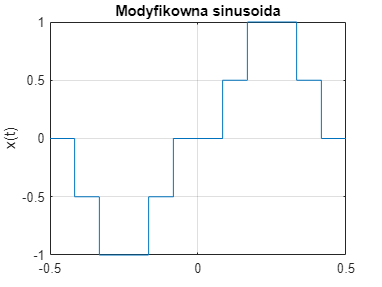

syms t t1 t2 offset x

T0 = 1.0;
t1 = -0.5;
t2 = t1 + T0;
offset = 0;

f0 = 1/T0;
w0 = 2*pi*f0;

BND = [t1,t2]+offset;
x = 0.5*(-rectangularPulse(-0.5+1/12, -1/12, t)-rectangularPulse(-0.5+1/6,-1/6, t) + rectangularPulse(1/12, 0.5-T0/12, t) +rectangularPulse(1/6,0.5-1/6, t));
figure;
fplot(x, BND),grid on, hold on
ylabel('x(t)')
title('Modyfikowna sinusoida')
hold off

### 3.3.2

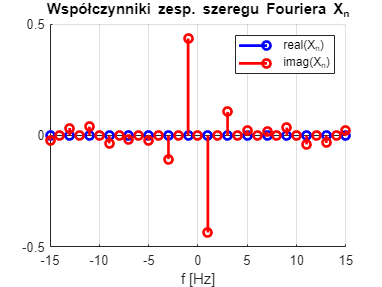

NT = 15;
X=[];
ind=-NT:NT;
for n = ind
    Xn = (1/T0)*int(x*exp(-1i*w0*n*t),t,BND);
    X(n+NT+1)=Xn;
end
figure; hold on
stem(ind*f0,real(X),'b','LineWidth',2);
xlabel('f [Hz]')
stem(ind*f0,imag(X),'r','LineWidth',2);
grid on
legend('real(X_n)','imag(X_n)','Location','NorthEast'),
title('Współczynniki zesp. szeregu Fouriera X_n')
hold off

### 3.3.3

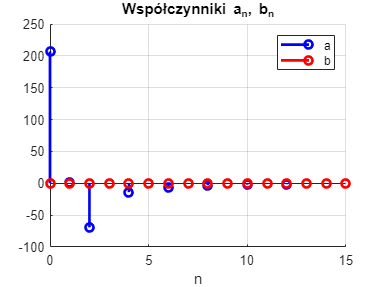

a=[];
b=[];
for n = 0:NT
    a(n+1) = (1/T0)*int(x*cos(w0*n*t),t,BND);
    b(n+1) = (1/T0)*int(x*sin(w0*n*t),t,BND);
end

figure(3); hold on, grid on
stem(0:NT,a,'b','LineWidth',2);
xlabel('n')
stem(0:NT,b,'r','LineWidth',2);
legend('a','b'),
title('Współczynniki a_n, b_n')
hold off

### 3.3.4

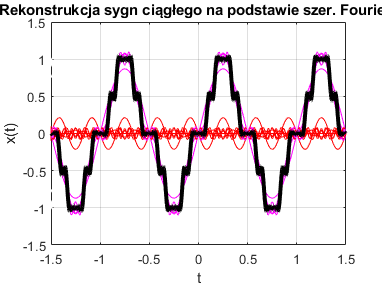

step = (BND(2)-BND(1))/1000;
tt = [BND(1)-T0 : step : BND(2)+T0];
xx = zeros(1,length(tt));
xx = xx + a(1);

figure;
plot(tt,xx,'m');  grid on, hold on;
plot([tt(1),tt(2)],[max(xx)-0.1,min(xx)+0.1], 'r'),
pause(0.5)
xlabel('t'); ylabel('x(t)');

for n=1:NT
    xx_n=2*(a(n+1)*cos(w0*n*tt)+b(n+1)*sin(w0*n*tt));
    xx = xx + xx_n;
    plot(tt,xx_n,'r');
    plot(tt,xx,'m');
    plot([tt(1),tt(2)],[max(xx)-0.1,min(xx)+0.1],'w.')
    title(sprintf('n = %d',n+1));
    pause(0.5)
end
 
plot(tt,xx,'k','LineWidth',3); grid on, hold on
plot([tt(1),tt(2)],[max(xx)-0.1,min(xx)+0.1],'w.')
title('Rekonstrukcja sygn ciągłego na podstawie szer. Fouriera')
hold off

### 3.3.5

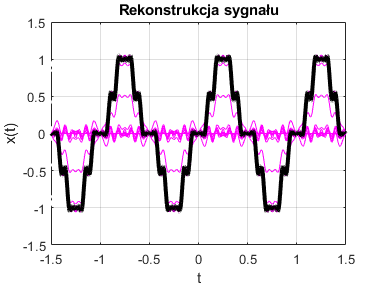

xx = zeros(1,length(tt));

figure(5);
plot(tt,xx,'m');  grid on, hold on;
pause(0.5)
xlabel('t'); ylabel('x(t)');

for n=-NT:NT
    xx_n=X(n+NT+1)*exp(1i*w0*n*tt);
    xx = xx + xx_n;
    pause(0.5);
    plot(tt,real(xx),'m');
    plot([tt(1),tt(2)],[max(real(xx))-0.1, min(real(xx))+0.1],'w.')
end

plot(tt,real(xx),'k','LineWidth',3); grid on, hold on
plot([tt(1),tt(2)],[max(real(xx))-0.1,min(real(xx))+0.1],'w.')
title('Rekonstrukcja sygnału')
hold off


% błąd aproksymacji

syms err
pars_wave = int(x.^2,t,BND)/T0

$$pars\_wave = \frac{5}{12}$$

pars_series = sum(abs(X).^2)

pars_series = 0.4111

err_abs = double(abs(pars_wave - pars_series))

err_abs = 0.0056

err_rel = double(err_abs / pars_wave) * 100

err_rel = 1.3464

### 3.3.6 A)

syms skut
skut = sqrt(int(sin(t)^2,t,[0 2*pi])/(2*pi));
skd = double(skut)

skd = 0.7071

### 3.3.6 B)

skut1 = sqrt(int(x^2,t,BND)/T0)

$$skut1 = \frac{\sqrt{3}\,\sqrt{5}}{6}$$

### 3.3.6 C)

skut_xx = sqrt(trapz(real(xx(1001:2001)).^2)/1000)

skut_xx = 0.6411

### 3.3.7

s = 0;
for n = 2:NT
    s = s + abs(a(n+1)+1j*b(n+1)).^2/2;
    thd = sqrt(s)/(abs(a(2)+1j*b(2))/sqrt(2))
end

thd = 0

thd = 0.2440

thd = 0.2440

thd = 0.2498

thd = 0.2498

thd = 0.2527

thd = 0.2527

thd = 0.2655

thd = 0.2655

thd = 0.2806

thd = 0.2806

thd = 0.2910

thd = 0.2910

thd = 0.2951